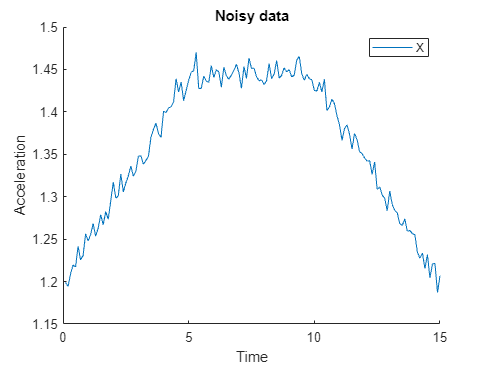

clear

%2 different approaches to error. First is just finding the error and
%compiling separate lists then running those through the Kalman Filter.
%Second is creating an array containing the errors then adjusting MN (measurement noise) accordingly

%Creating sample data. Aiming for a linear acceleration and deceleration.
dt=0.1;
t=dt:dt:15;
MN = 1;
PN =1;

%Making data
%Data given will be in the form of 1.2-1.4 mA/g
%Trying to simulate a object taking a turn 
Base = 1.2;

Xa=Base + 0.05*t(1:(length(t))/3);
Xb=max(Xa)*ones(1,length(Xa));
Xc=Base -Xa + max(Xa);

XAccel = cat(2,cat(2,Xa,Xb),Xc);


%Adding noise to each point
error = 0.005;
rand = (randn(1,length(XAccel))*2 - 1) * error;
for i=1: length(XAccel)
    NoiseX(i) = XAccel(i) + rand(i);
end

figure; hold on;
plot(t,NoiseX)
xlabel('Time')
ylabel('Acceleration')
legend('X')
title('Noisy data')

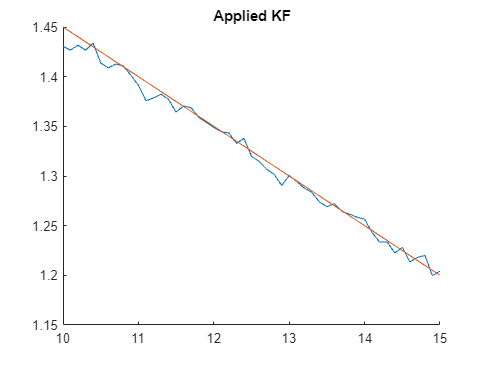



%For now just trying to get kalman working for 1 input along with error
%stuff 

figure; hold on;
plot(t,KF(NoiseX, t, MN, PN))
plot(t,XAccel)
xlim([10,15])
title('Applied KF')

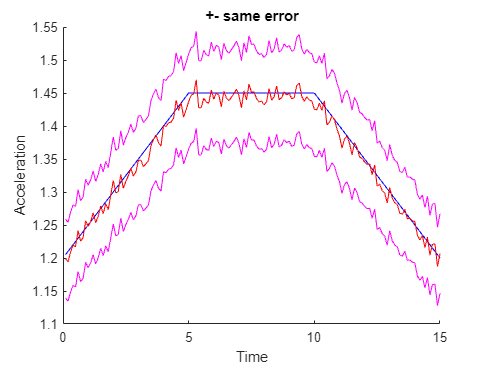


%Lets say each point has a 5% error attached to it (in addition to noise)
Upper=zeros(1,length(t));
Lower=zeros(1,length(t));
for i=1:length(t)
    Upper(i) = NoiseX(i)*1.05;
    Lower(i) = NoiseX(i)*0.95;
end


%Plotting all 
figure; hold on;
plot(t,Lower,'m')
plot(t,Upper,'m')
plot(t,XAccel,'b')
plot(t,NoiseX,'r')
xlabel('Time')
ylabel('Acceleration')
title('+- same error')

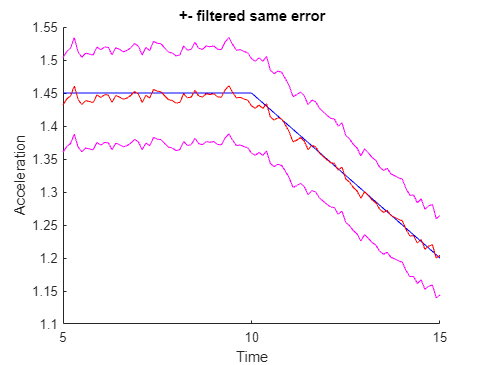


figure; hold on;
plot(t,KF(Upper, t, MN, PN),'m')
plot(t,KF(Lower, t, MN, PN),'m')
plot(t,XAccel,'b')
plot(t,KF(NoiseX, t, MN, PN),'r')
xlabel('Time')
ylabel('Acceleration')
title('+- filtered same error')
xlim([5 15])

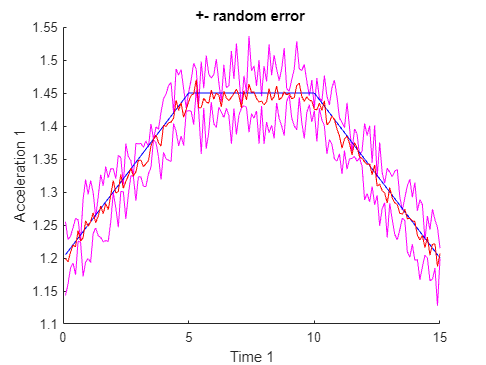


%Doing same again but if each point has different uncertainties attached to
%it 

Upper1=zeros(1,length(t));
Lower1=zeros(1,length(t));

%Creating random error between 0% and 5%
clear rand 

%rand takes value from 0-1(uniform dist), so /20 gets between 0-5%.
%Not entirely convinced its giving the correct results 
err=rand(length(t),1);
for i=1:length(t)
   
    Upper1(i) = NoiseX(i)*(1+err(i)/20);
    Lower1(i) = NoiseX(i)*(1-err(i)/20);
end

%Plotting all 
figure; hold on;
plot(t,Lower1,'m')
plot(t,Upper1,'m')
plot(t,XAccel,'b')
plot(t,NoiseX,'r')
xlabel('Time 1')
ylabel('Acceleration 1')
title('+- random error ')

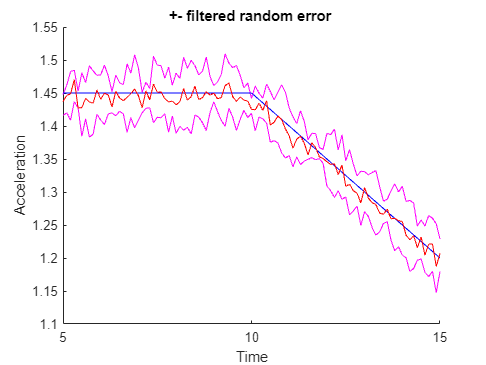


figure; hold on;
plot(t,KF(Lower1, t, MN, PN),'m')
plot(t,KF(Upper1, t, MN, PN),'m')
plot(t,XAccel,'b')
plot(t,NoiseX,'r')
xlabel('Time')
ylabel('Acceleration')
title('+- filtered random error ')
xlim([5 15])


%Method 2
dt=0.1;
t=dt:dt:15;
MN=1

MN = 1

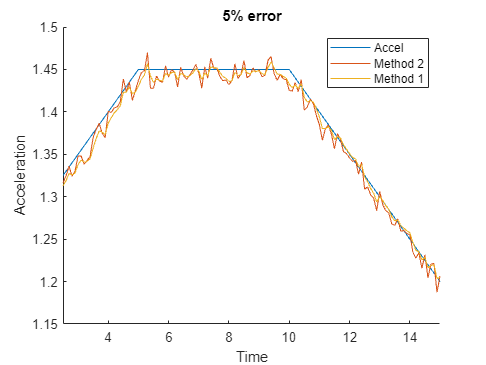

PN =0.5;                    %Method 1 is massively affected when PN<<MN, whereas Method 2 stays fairly accurate regardless 
err = 0.05*ones(1,length(t));

figure; hold on ; 
plot(t,XAccel)
plot(t, KFVar(NoiseX, t, err, PN))
plot(t, KF(NoiseX, t, MN, PN))
legend('Accel','Method 2', 'Method 1')
xlim([2.5 15])
xlabel('Time')
ylabel('Acceleration')
title('5% error')

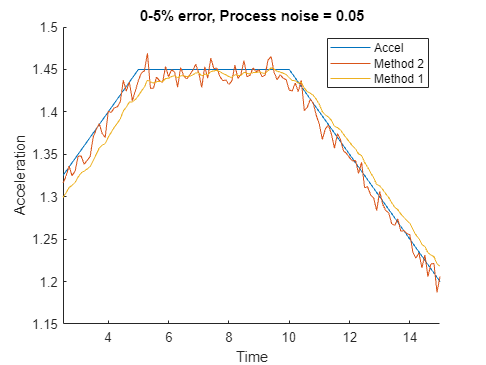

%Method 2 clearly looks smoother 

%Random errors now, not just 5% on each 
dt=0.1;
t=dt:dt:15;
err1 = rand(1, length(t))/20;  % errors now anywhere between 0 and 5%

PN =0.05; 

figure; hold on ; 
plot(t,XAccel)
plot(t, KFVar(NoiseX, t, err1, PN))
plot(t, KF(NoiseX, t, MN, PN))
legend('Accel','Method 2', 'Method 1')
xlim([2.5 15])
xlabel('Time')
ylabel('Acceleration')
title('0-5% error, Process noise = 0.05')

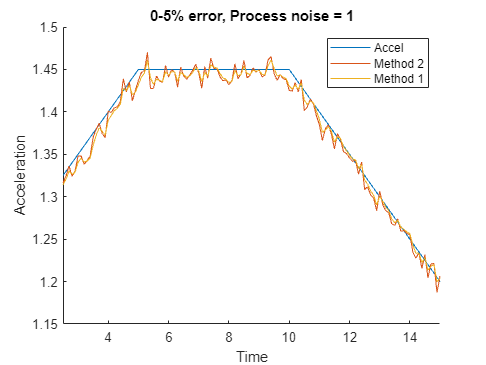


PN =1; 

figure; hold on ; 
plot(t,XAccel)
plot(t, KFVar(NoiseX, t, err1, PN))
plot(t, KF(NoiseX, t, MN, PN))
legend('Accel','Method 2', 'Method 1')
xlim([2.5 15])
xlabel('Time')
ylabel('Acceleration')
title('0-5% error, Process noise = 1')





%Process noise to be determined based on the environment.
%Large PN for systems requiring slower adjustment ( large maritime vessels)
%Smaller PN for smaller maritime vessels 

function [filteredAccel] = KF(Accel, t, MN, PN)

    Transition=1;       %State transition
    Measurement=1;      %Measurement Matrix

    StateEst = 0;     %Initial state estimate
    InitCov=1;        %Initial state covariance 
    filteredAccel=zeros(1,length(t));

    for i = 1:length(t)
        % Prediction
        XPred = Transition*StateEst;             
        PredCov = Transition*InitCov*Transition' + PN;              

        % Updating
        Gain = PredCov*Measurement'/(Measurement*PredCov*Measurement' + MN); 
        StateEst = XPred + Gain*(Accel(i) - Measurement*XPred);
        InitCov = (1 - Gain*Measurement)*PredCov;         
    
        filteredAccel(i) = StateEst;
    end 
end

function [filteredAccel] = KFVar(Accel, t, err, PN)

    Transition=1;       %State transition
    Measurement=1;      %Measurement Matrix

    StateEst = 0;     %Initial state estimate
    InitCov=1;        %Initial state covariance 
    filteredAccel=zeros(1,length(t));

    for i = 1:length(t)
        % Prediction
        XPred = Transition*StateEst;             
        PredCov = Transition*InitCov*Transition' + PN;              

        % Updating
        Gain = PredCov*Measurement'/(Measurement*PredCov*Measurement' + (Accel(i) * err(i))^2); 
        StateEst = XPred + Gain*(Accel(i) - Measurement*XPred);
        InitCov = (1 - Gain*Measurement)*PredCov;         
    
        filteredAccel(i) = StateEst;
    end 
end